## Phys_Algo: 3D Phase Stretch Transform (PST) for Live Cell Tracking

Derived from work of: M. Asghari and Madhuri Suthar, Jalali Lab, Department of Electrical and Computer Engineering,  UCLA

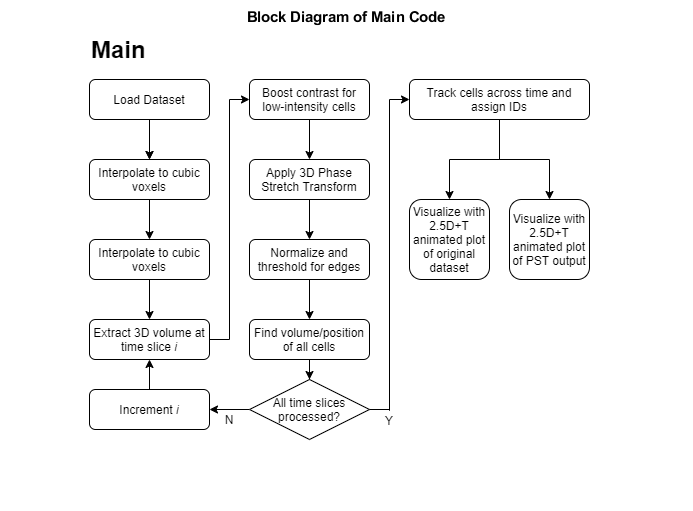

% Initial Setup 
clc; % clear screen
close all; % close all figures
addpath('src/'); % script source directory
addpath('lib/'); % 3rd party script source directory

flowchart = imread('main_diagram.png');

imshow(flowchart);
title("Block Diagram of Main Code");

### Fluo-N3DH-CHO Dataset

clear variables; % clear all variables

% Load CHO dataset - voxel size 0.202 x 0.202 x 1.0 microns
cell_dataset = cell_dataset('data/Fluo-N3DH-CHO/01/');

% Preallocate PST output for GIF visualization
edge_dataset = zeros(size(cell_dataset), 'logical');

% Repeat Z axis 5x so that voxels are approximately cubic
% This will be re-decimated after binarization of PST output
z_scale = 5; % 1.0 micron / 5 ~= 0.202 microns
cell_dataset = repelem(cell_dataset, 1, 1, z_scale, 1);

% Iterate over all time slices
n_time_slices = size(cell_dataset, 4);
% n_time_slices = 10; % Override for testing
centroids = cell(1, n_time_slices);
for time_slice = 1:n_time_slices
    % Operate on one time slice at a time
    volume = cell_dataset(:,:,:,time_slice);

Configure the parameters for pre-PST contrast boost, the PST itself, and post-PST edge detection

    handles.pre_threshold = 0.1; 
    handles.pre_end_threshold = 0.25; 
    handles.pre_clip_limit = 0.05; 
    % low-pass filtering (also called localization) parameter
    handles.LPF=0.1; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)
    % PST parameters
    handles.Phase_strength=10;  % PST  kernel Phase Strength 
    handles.Warp_strength=30.48;  % PST Kernel Warp Strength
    % Thresholding parameters (for post processing)
    handles.Post_Threshold = 0.005; % PST threshold to detect a binary edge


Apply the PST to extract binary edges

    volume = PST_pre(volume, handles);
    [volume_pst_features, ~] = PST_ND(volume, handles);
    [volume_edges] = PST_post(volume_pst_features, handles);    

Decimate our binarized PST output in the Z axis back to the original dataset dimensions

Note: The range decimated is hand-tuned for this dataset. The top 5 layer exhibit odd, almost aliased output and are discarded.

    volume_edges = volume_edges(:,:,4:4:20); % Decimate, redundant info
    edge_dataset(:,:,:,time_slice) = volume_edges; % Save edge output for visualization

Find the centroids of each cell in the image using the PST edges

    % Sigmas used for Difference of Gaussians algorithm
    sigmas = [10, 15, 20, 25];
    centroids{time_slice} = find_cells(volume_edges, sigmas, z_scale);

On the first time slice, generate images showing an example 2D slice of our output

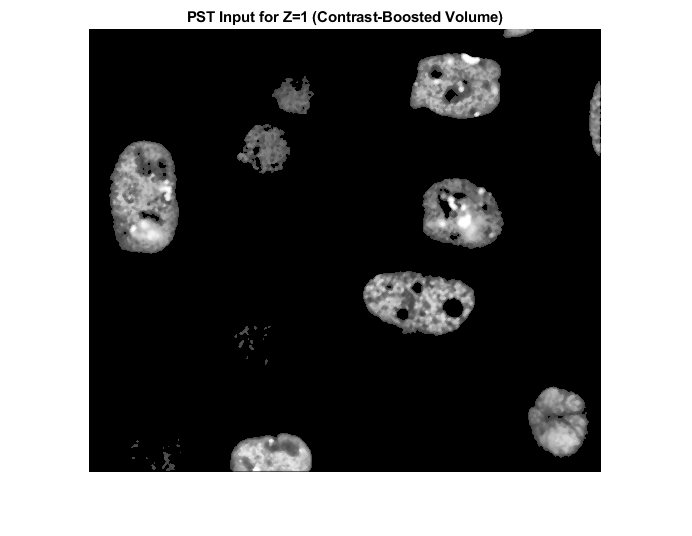

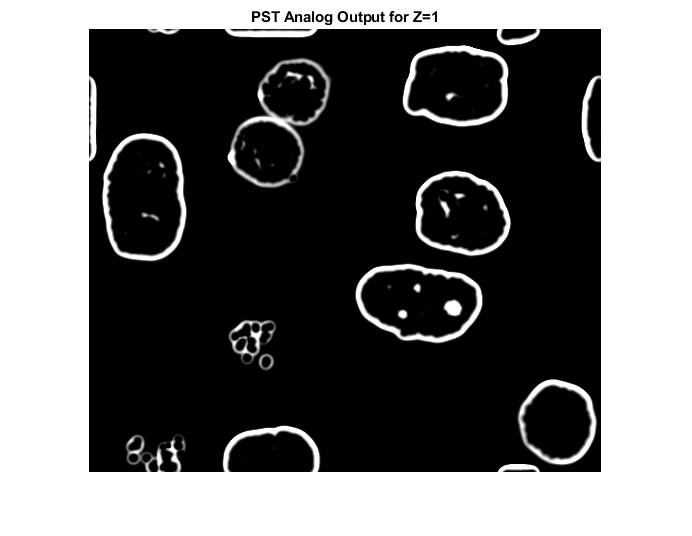

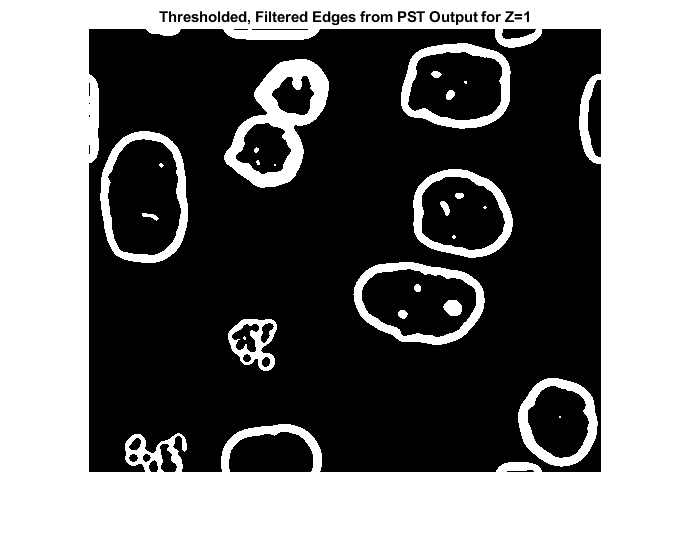

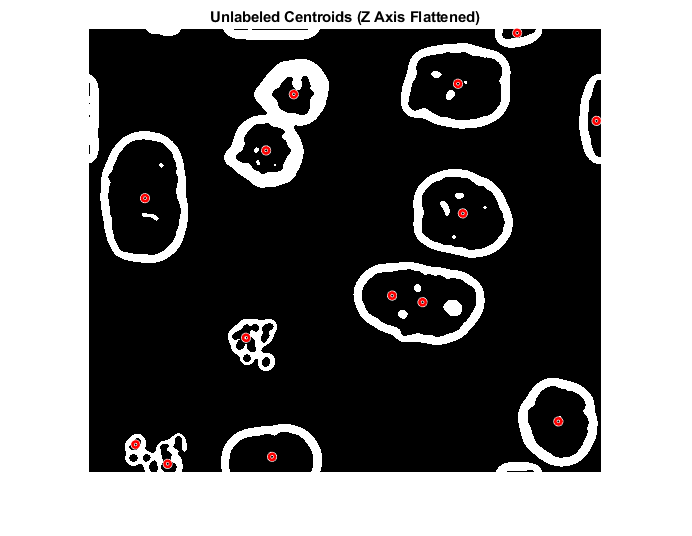

    if time_slice == 1
        figure; imshow(volume(:,:,1));
        title("PST Input for Z=1 (Contrast-Boosted Volume)");
        figure; imshow(volume_pst_features(:,:,1));
        title("PST Analog Output for Z=1");
        figure; imshow(volume_edges(:,:,1));
        title("Thresholded, Filtered Edges from PST Output for Z=1");
        figure; imshow(volume_edges(:,:,1));
        for i = 1:size(centroids{time_slice}, 2)
            viscircles(centroids{time_slice}(i).centroid(1:2), 3);
        end
        title("Unlabeled Centroids (Z Axis Flattened)");
    end
end

Assign each cell a unique ID that spans across time to track the location of each unique cell

% Debugging: Reset all IDs to their expected value (-1)
for i = 1:size(centroids, 2)
    for j = 1:size(centroids{i}, 2)
        centroids{i}(j).ID = -1;
    end
end

% Track!
centroids = track_cells(centroids);

Visualize the centroid tracking with both the original dataset and the PST output

visualize_2p5d_T('tracking_cells_CHO.gif', ...
    cell_dataset(:,:,1:z_scale:size(cell_dataset, 3),1:n_time_slices), ...
    centroids, [2,3]);
visualize_2p5d_T('tracking_pst_CHO.gif', ...
    edge_dataset(:,:,:,1:n_time_slices), ...
    centroids, [2,3]);

assert(0); % Don't execute below here

Assertion failed.

### Fluo-C3DL-MDA231 Dataset

clear variables; % clear all variables

% Load C3DL dataset - voxel size 1.242 x 1.242 x 6.0 microns
cell_dataset = cell_dataset('data/Fluo-C3DL-MDA231/01/');

% Preallocate PST output for GIF visualization
edge_dataset = zeros(size(cell_dataset), 'logical');

% Repeat Z axis 5x so that voxels are approximately cubic
% This will be re-decimated after binarization of PST output
z_scale = 5; % 6.0 micron / 5 ~= 1.2 microns
cell_dataset = repelem(cell_dataset, 1, 1, z_scale, 1);

% Iterate over all time slices
n_time_slices = size(cell_dataset, 4);
n_time_slices = 10; % Override for testing
centroids = cell(1, n_time_slices);
for time_slice = 1:n_time_slices
    % Operate on one time slice at a time
    volume = cell_dataset(:,:,:,time_slice);

    handles.pre_threshold = 0.03;
    handles.pre_end_threshold = 0.25;
    handles.pre_clip_limit = 0.2;
    % low-pass filtering (also called localization) parameter
    handles.LPF=0.2; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)

    % PST parameters
    handles.Phase_strength= 1;  % PST  kernel Phase Strength
    handles.Warp_strength=5.48;  % PST Kernel Warp Strength
    % Thresholding parameters (for post processing)
    handles.Post_Threshold = 0.03; % PST threshold to detect a binary edge

    volume = PST_pre(volume, handles);
    [volume_pst_features, ~] = PST_ND(volume, handles);
    [volume_edges] = PST_post(volume_pst_features, handles);

    volume_edges = volume_edges(:,:,1:z_scale:150); % Decimate, redundant info
    edge_dataset(:,:,:,time_slice) = volume_edges; % Save edge output for visualization

    % Sigmas used for Difference of Gaussians algorithm
    sigmas = [10, 15, 20, 25];
    centroids{time_slice} = find_cells(volume_edges, sigmas, z_scale);

    if time_slice == 1
        figure; imshow(volume(:,:,44));
        title("PST Input for Z=1 (Contrast-Boosted Volume)");
        figure; imshow(volume_pst_features(:,:,44));
        title("PST Analog Output for Z=1");
        figure; imshow(volume_edges(:,:,ceil(44/5)));
        title("Thresholded, Filtered Edges from PST Output for Z=1");
        figure; imshow(volume_edges(:,:,ceil(44/5)));
        for i = 1:size(centroids{time_slice}, 2)
            viscircles(centroids{time_slice}(i).centroid(1:2), 3);
        end
        title("Unlabeled Centroids (Z Axis Flattened)");
    end
end

% Track!
centroids = track_cells(centroids);

Visualize the centroid tracking with both the original dataset and the PST output

visualize_2p5d_T('tracking_cells_MDA231.gif', ...
    cell_dataset(:,:,1:z_scale:size(cell_dataset, 3),1:n_time_slices), ...
    centroids, [5,6]);
visualize_2p5d_T('tracking_pst_MDA231.gif', ...
    edge_dataset(:,:,:,1:n_time_slices), ...
    centroids, [5,6]);

assert(0); % stop execution

### Fluo-C3DH-A549 Dataset

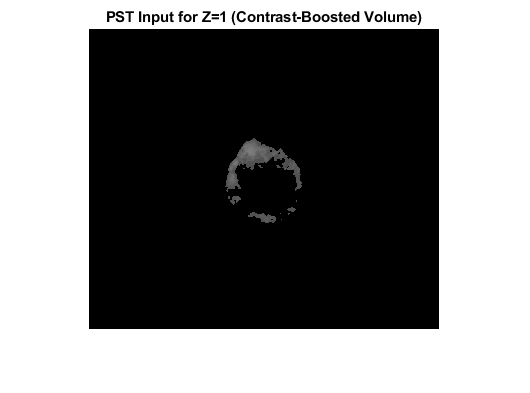

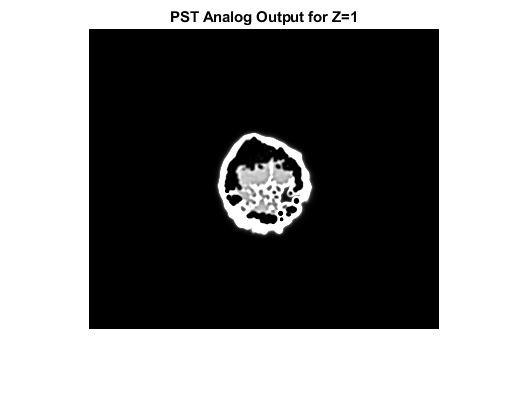

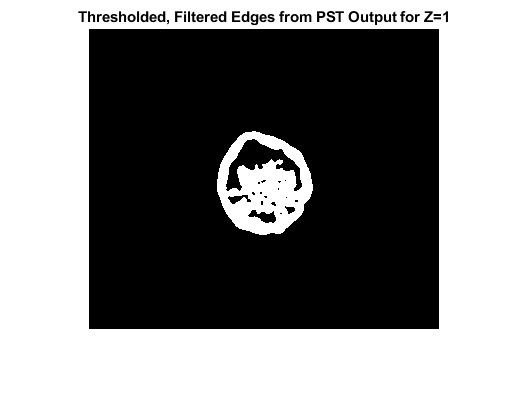

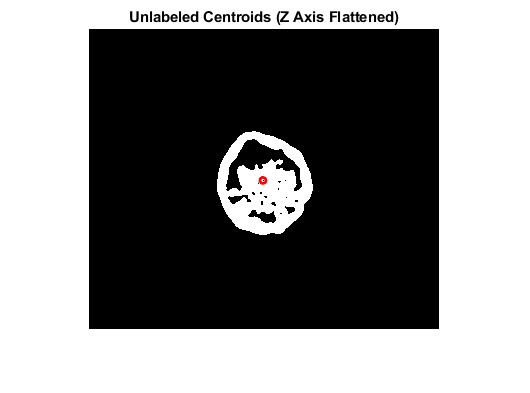

clear variables; % clear all variables

% Load C3DL dataset - voxel size 1.242 x 1.242 x 6.0 microns
cell_dataset = cell_dataset('data/Fluo-C3DH-A549/01/');
z_scale = 5; % 6.0 micron / 5 ~= 1.2 microns

% Repeat Z axis 5x so that voxels are approximately cubic
cell_dataset = repelem(cell_dataset, 1, 1, z_scale, 1);

% Iterate over all time slices
n_time_slices = size(cell_dataset, 4);
centroids = cell(1, n_time_slices);
for time_slice = 1:n_time_slices
    % Operate on one time slice at a time
    volume = cell_dataset(:,:,:,time_slice);
    handles.pre_threshold = 0; 
    handles.pre_end_threshold = 0.3; 
    handles.pre_clip_limit = 0.05; 
    % low-pass filtering (also called localization) parameter
    handles.LPF=0.2; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)

    % PST parameters
    handles.Phase_strength= 10;  % PST  kernel Phase Strength
    handles.Warp_strength=15.48;  % PST Kernel Warp Strength 
    % Thresholding parameters (for post processing)
    handles.Post_Threshold = 0.03; % PST threshold to detect a binary edge

    volume = PST_pre(volume, handles);
    [volume_pst_features, ~] = PST_ND(volume, handles);
    volume_pst_features(volume_pst_features < 0.001) = 0;
    [volume_edges] = PST_post(volume_pst_features, handles);

    volume_edges = volume_edges(:,:,1:z_scale:145); % Decimate, redundant info
    edge_dataset(:,:,:,time_slice) = volume_edges; % Save edge output for visualization

    % Sigmas used for Difference of Gaussians algorithm
    sigmas = [10, 15, 20, 25];
    centroids{time_slice} = find_cells(volume_edges, sigmas, z_scale);

    if time_slice == 1
        figure; imshow(volume(:,:,77));
        title("PST Input for Z=1 (Contrast-Boosted Volume)");
        figure; imshow(volume_pst_features(:,:,77));
        title("PST Analog Output for Z=1");
        figure; imshow(volume_edges(:,:,ceil(77/5)));
        title("Thresholded, Filtered Edges from PST Output for Z=1");
        figure; imshow(volume_edges(:,:,ceil(77/5)));
        for i = 1:size(centroids{time_slice}, 2)
            viscircles(centroids{time_slice}(i).centroid(1:2), 3);
        end
        title("Unlabeled Centroids (Z Axis Flattened)");
    end
end


% Track!
centroids = track_cells(centroids);

visualize_2p5d_T('tracking_cells_A529.gif', ...
    cell_dataset(:,:,1:z_scale:size(cell_dataset, 3),1:n_time_slices), ...
    centroids, [6,5]);
visualize_2p5d_T('tracking_pst_A529.gif', ...
    edge_dataset(:,:,:,1:n_time_slices), ...
    centroids, [6,5]);